%initializing variables
clear
days = 100;
grid = zeros(10,10);
camera = [3, 3];
camera_x = 3;
camera_y = 3;
animal_position = zeros(10,10);
animal_position(5,5) = 1;
track_path = zeros(10,2);
leop_paths = struct();
camera_track = zeros(days, 1);
M = zeros(1000, 1);
times_max = 1000;

%simulation
for N = 1:12
    for times = 1:times_max
        camera_track = zeros(days, 1);
        for leop = 1:N
            start_x = ceil(10*rand);
            start_y = ceil(10*rand);
                %start from a random position in the 10x10 grid
            for day = 1:days
                track_path(day, :) = [start_x, start_y];
                    %track path of the leopard from initial position
                if [start_x, start_y] == [camera_x, camera_y]
                    camera_track(day) = 1;
                        %flag any day where the camera takes a shot
                end 
                move = move_position(start_x, start_y);                     
                            %see function: move_position
                [start_x, start_y] = next_position(move, start_x, start_y);
                            %see function: next_position
            end
            name = ['leo', num2str(leop)];
            leop_paths.(name) = track_path;
        end
        M(times) = sum(camera_track);
     end
     prob(N) = sum(M==5)/times_max;
end

**Plotting sample path of three snow leopards in the grid**

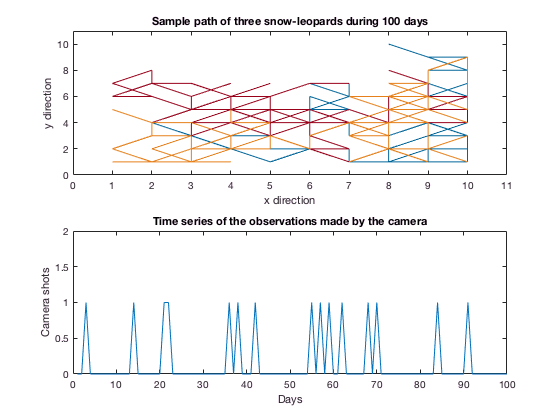

clf
subplot(2,1,1)
plot(leop_paths.leo1(:,1), leop_paths.leo1(:,2), '-', 'Color', [0 0.4 0.6])
hold on
plot(leop_paths.leo2(:,1), leop_paths.leo2(:,2), '-', 'Color', [0.6 0 0.1])
plot(leop_paths.leo3(:,1), leop_paths.leo3(:,2), '-', 'Color', [0.9 0.5 0.1])
axis([0 11 0 11])
xlabel('x direction')
ylabel('y direction')
title('Sample path of three snow-leopards during 100 days')
subplot(2,1,2)
plot(camera_track, '-')
axis([0 100 0 2])
xlabel('Days')
ylabel('Camera shots')
title('Time series of the observations made by the camera')

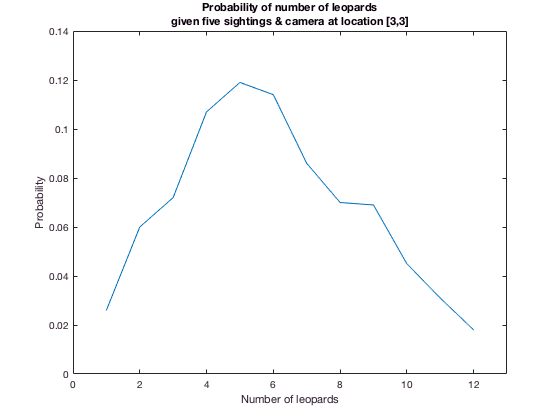

clf
plot(prob, '-')
xlabel('Number of leopards')
ylabel('Probability')
title({'Probability of number of leopards';
    'given five sightings & camera at location [3,3]'})
axis([0 13 0 0.14])